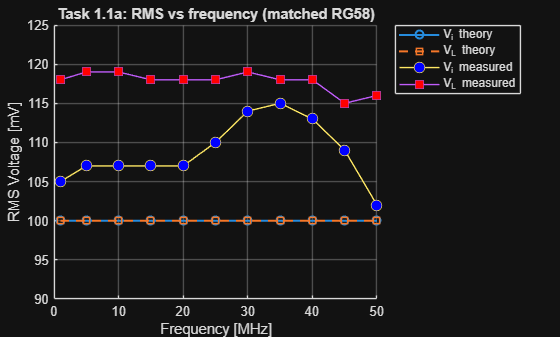

% --- Overleaf repo path---
repo = 'C:\Users\Mads2\Documents\Measurement-report';
cd(repo);
if ~exist('fig','dir'), mkdir fig; end
%----------------------------------------------------

%TASK 1.1a
% --- Data ---
f_MHz = [1 5 10 15 20 25 30 35 40 45 50];
Vi_mV = [105 107 107 107 107 110 114 115 113 109 102];
VL_mV = [118 119 119 118 118 118 119 118 118 115 116];
phi_deg_meas = [4 18 40 58 76 98 112 132 150 167 180];

% --- Theory parameters ---
ell = 2.06;                 % [m] DUT length
VF  = 0.66;                 % RG58 velocity factor
up  = VF*3e8;               % [m/s]
tau = ell/up;               % [s] ~ 10 ns

% --- Theory curves at the SAME frequencies as measured ---
Vi_th = 100 * ones(size(f_MHz));   % [mV], matched divider
VL_th = Vi_th;                     % same (lossless)
phi_deg_th = 360 * (f_MHz*1e6) * tau;  % [deg]

% --- Plot RMS voltages ---
figure; hold on; grid on;
plot(f_MHz, Vi_th, 'o-', 'LineWidth',1.5);
plot(f_MHz, VL_th, 's--', 'LineWidth',1.5);
plot(f_MHz, Vi_mV, 'o-', 'MarkerSize',8, 'MarkerFaceColor','b');
plot(f_MHz, VL_mV, 's-', 'MarkerSize',8, 'MarkerFaceColor','r');
xlabel('Frequency [MHz]'); ylabel('RMS Voltage [mV]');
legend('V_i theory','V_L theory','V_i measured','V_L measured','Location','bestoutside');
title('Task 1.1a: RMS vs frequency (matched RG58)');
ylim([90 125]);

% Export to overleaf
set(gcf,'PaperPositionMode','auto');
exportgraphics(gcf,'fig/task11a_rms.pdf','ContentType','vector');   % crisp PDF
exportgraphics(gcf,'fig/task11a_rms.png','Resolution',300);         % optional preview

disp('Saved fig/task11a_rms.[pdf|png]');

Saved fig/task11a_rms.[pdf|png]


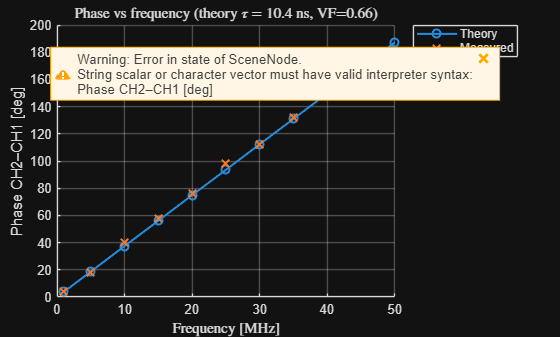



% --- Plot phase ---
figure; hold on; grid on;
plot(f_MHz, phi_deg_th, 'o-', 'LineWidth',1.5);
plot(f_MHz, phi_deg_meas, 'x', 'MarkerSize',8, 'LineWidth',1.5);
xlabel('Frequency [MHz]','Interpreter','latex');
ylabel('Phase CH2–CH1 [deg]','Interpreter','latex');  
title(sprintf('Phase vs frequency (theory $\\tau=%.1f$ ns, VF=%.2f)', ...
              tau*1e9, VF),'Interpreter','latex');

legend('Theory','Measured','Location','bestoutside');

% Export to overleaf
set(gcf,'PaperPositionMode','auto');
exportgraphics(gcf,'fig/task11a_phase.pdf','ContentType','vector');
exportgraphics(gcf,'fig/task11a_phase.png','Resolution',300);

disp('Saved fig/task11a_phase.[pdf|png]');

Saved fig/task11a_phase.[pdf|png]




%Git integration to export graphs to overleaf
system('git add fig/*.pdf fig/*.png');
system('git commit -m "Update Task 1.1a figures"');

[main d439261] Update Task 1.1a figures
 4 files changed, 0 insertions(+), 0 deletions(-)


system('git push origin main');

To https://github.com/MadsRudolph/Measurement-report.git
   4556f27..d439261  main -> main


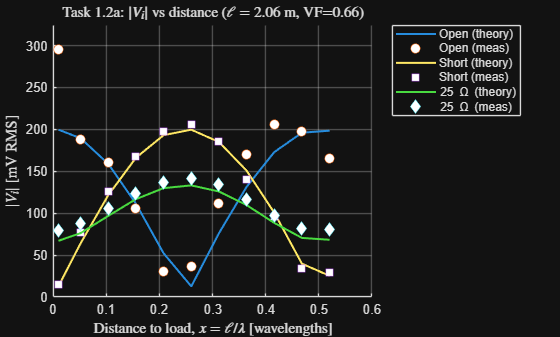

%% Task 1.2a – Vi vs distance to load in wavelengths

% --- Known parameters ---
Z0  = 50; Zg = 50; Vg = 0.200;      % source: 200 mV RMS, 50 Ω
ell = 2.06; VF = 0.66; up = VF*3e8; % cable length & velocity

% --- Frequencies (same for all cases) ---
f_MHz = [1 5 10 15 20 25 30 35 40 45 50];
f_Hz  = f_MHz*1e6;

% --- Distance to load in wavelengths ---
x = f_Hz * ell / up;   % unitless

% --- Measured Vi [mV] ---
Vi_OC_mV  = [295 188 160 106 30.3 36 111 170 206 197 165];
Vi_SC_mV  = [15.5 77 126 168 198 206 185 140 95.5 33.7 28.9];
Vi_25_mV  = [79.5 88 106 124 137 141 134 116 97 82.3 80.5];

% --- Theory Vi [mV] ---
beta = 2*pi*f_Hz/up;

% Open circuit: Zin = -jZ0 cot(beta*ell)
Zin_OC = -1j*Z0 .* cot(beta*ell);
Vi_OC_th = 1e3*abs(Vg .* Zin_OC ./ (Zg + Zin_OC));

% Short circuit: Zin = jZ0 tan(beta*ell)
Zin_SC =  1j*Z0 .* tan(beta*ell);
Vi_SC_th = 1e3*abs(Vg .* Zin_SC ./ (Zg + Zin_SC));

% 25 Ω load: general formula
ZL = 25;
Zin_25 = Z0 .* (ZL + 1j*Z0.*tan(beta*ell)) ./ (Z0 + 1j*ZL.*tan(beta*ell));
Vi_25_th = 1e3*abs(Vg .* Zin_25 ./ (Zg + Zin_25));

% --- Plot ---
figure; hold on; grid on;
plot(x, Vi_OC_th, '-', 'LineWidth',1.5);
plot(x, Vi_OC_mV, 'o', 'MarkerSize',7, 'MarkerFaceColor','w');
plot(x, Vi_SC_th, '-', 'LineWidth',1.5);
plot(x, Vi_SC_mV, 's', 'MarkerSize',7, 'MarkerFaceColor','w');
plot(x, Vi_25_th, '-', 'LineWidth',1.5);
plot(x, Vi_25_mV, 'd', 'MarkerSize',7, 'MarkerFaceColor','w');

xlabel('Distance to load, $x = \ell/\lambda$ [wavelengths]', 'Interpreter','latex');
ylabel('$|V_i|$ [mV RMS]', 'Interpreter','latex');
title(sprintf('Task 1.2a: $|V_i|$ vs distance ($\\ell=%.2f$ m, VF=%.2f)', ell, VF), ...
      'Interpreter','latex');
legend('Open (theory)','Open (meas)', ...
       'Short (theory)','Short (meas)', ...
       '25 \Omega (theory)','25 \Omega (meas)', ...
       'Location','bestoutside');

ylim([0, max([Vi_OC_mV,Vi_SC_mV,Vi_25_mV,Vi_OC_th,Vi_SC_th,Vi_25_th])*1.1]);

% --- Export to Overleaf repo ---
set(gcf,'PaperPositionMode','auto');
exportgraphics(gcf,'fig/task12a_vi.pdf','ContentType','vector');   % vector PDF (recommended)
exportgraphics(gcf,'fig/task12a_vi.png','Resolution',300);         % optional PNG preview

disp('Saved fig/task12a_vi.[pdf|png]');

Saved fig/task12a_vi.[pdf|png]



% --- Export to Overleaf repo ---
system('git add fig/task12a_vi.pdf fig/task12a_vi.png');
system(sprintf('git commit -m "Add/Update Task 1.2a figure (%s)"', datestr(now)));

[main d4887ab] Add/Update Task 1.2a figure (25-Sep-2025 23:16:06)
 2 files changed, 0 insertions(+), 0 deletions(-)
 create mode 100644 fig/task12a_vi.pdf
 create mode 100644 fig/task12a_vi.png


system('git push origin main');

To https://github.com/MadsRudolph/Measurement-report.git
   d439261..d4887ab  main -> main


%TASK 1.3a
Z0  = 50;
ell = 2.01;          % m (your measured cable+connectors)
up  = 0.66*3e8;      % m/s (or compute from your measured Δf)
% ---- Measured extrema ----
Vi_max_mV = 139;           % e.g., [132 129 131]
f_max_MHz = 48;           % their frequencies
Vi_min_mV = 80;           % e.g., [88 90 89]
f_min_MHz = 24;           % their frequencies

% --- VSWR & |Gamma| ---
S = Vi_max_mV / Vi_min_mV;  
rho = (S-1)/(S+1);             % |Gamma_L|

% --- Angle of Gamma from one (or average of many) maxima ---
fm = mean(f_max_MHz)*1e6;      % Hz
ang = mod(4*pi*ell*fm/up, 2*pi);  % radians, using a MAX
% If you used a MIN instead, do: ang = mod(4*pi*ell*fm/up + pi, 2*pi);

GammaL = rho * exp(1j*ang);    % complex reflection coefficient
ZL = Z0 * (1 + GammaL) / (1 - GammaL);

fprintf('VSWR S=%.3f, |Gamma|=%.3f, angle=%.1f deg\n', S, rho, rad2deg(ang));

VSWR S=1.738, |Gamma|=0.269, angle=350.8 deg


fprintf('Estimated load: ZL = %.2f %+.2fj ohms\n', real(ZL), imag(ZL));

Estimated load: ZL = 85.77 -7.94j ohms
